# Tema 3

**Pb. 4 **Să se studieze teoretic şi experimental condiţionarea problemei determinării

rădăcinilor ecuaţiei polinomiale x^n + a1*x^(n−1) + a2*x^(n−2) + · · · + an = 0 (1) cunoscându-se coeficienţii. Se va scrie o rutină pentru calculul numărului

de condiţionare al fiecărei rădăcini şi se va studia grafic efectul

perturbării fiecărui coeficient cu o variabilă aleatoare normală cu media

0 şi dispersia 10^(−10). Aplicaţie pentru ecuaţiile

(x − 1)*(x − 2)* . . .* (x − n) = 0

şi (1) pentru ak = 2^(−k). Se va lua ca exemplu practic pentru testare

n = 20. Ce se întâmplă dacă perturbaţia urmează legea uniformă?

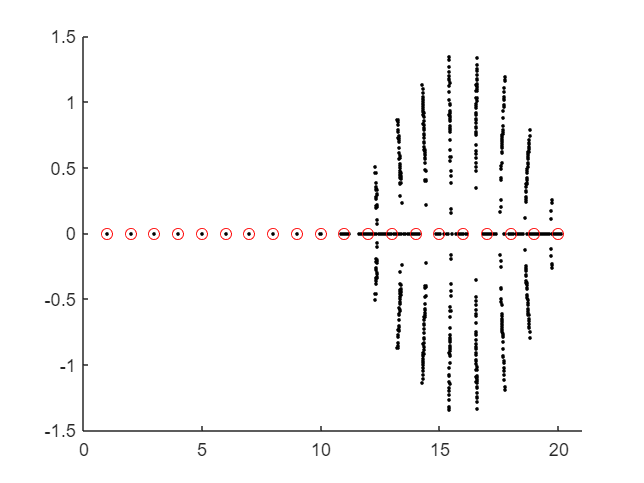

p3_v1()

function  p3_v1()
clf; hold on;
n=20;

a=poly(1:n);
 for i=1:100
   vect = randn(1,n+1) * 1e-10;
   ap = a+vect;
   r=roots(ap);
   plot(real(r),imag(r),'.k');
 
 end
 plot(1:n,zeros(1,n),'or');
 xlim([0 n+1])
end